# Plot multipoles for a given symmetry group

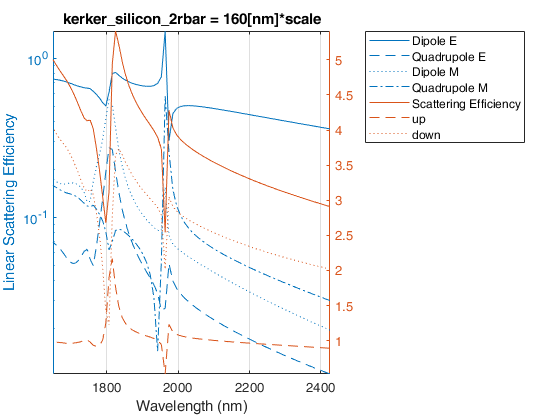

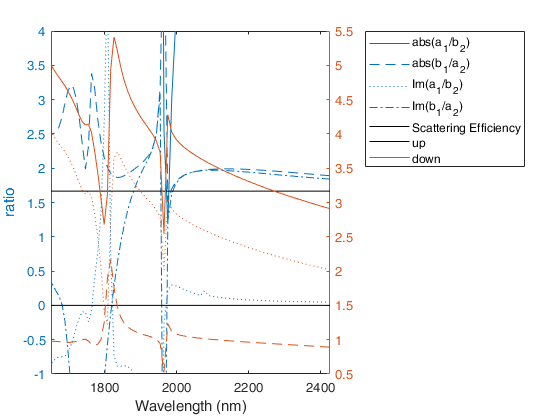

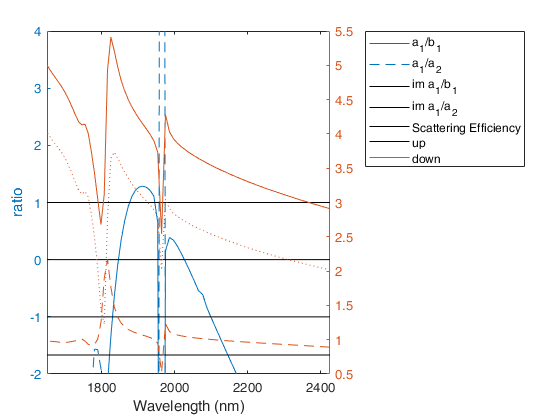

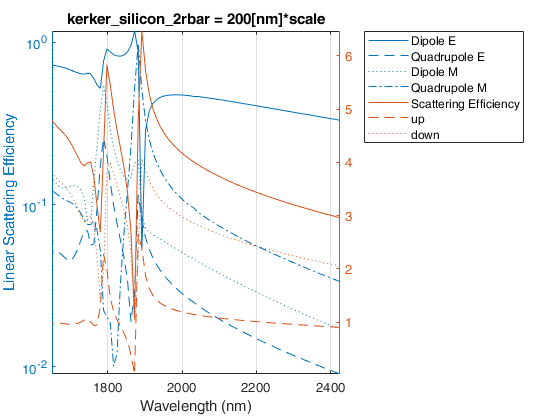

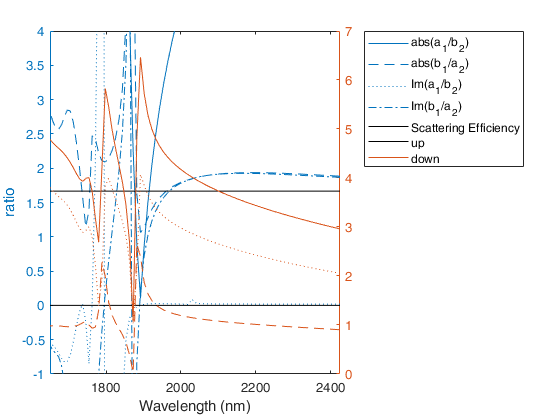

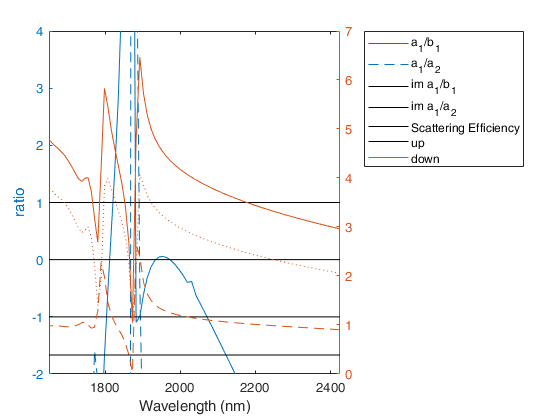

clear;
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\analysis');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\config\sweeps');
addpath('C:\Users\Matthew\Documents\MATLAB\COMSOL\jobs\completed');

symmetry_group = Mie;

for job = "kerker_slab_silicon_1"
    eval(job);
    load([options.output_dir_final 'sweep_data.mat']);
    extra_options = matthew_extra_options(options);
    
    for study_num = [8 10]%1:height(sweep_data)
        E = [];
        M = [];
        derived_values = sweep_data(study_num,:).DerivedValues{1};
        wlengths = 299792458./derived_values.signal.freq;

        
        fig = figure;
        yyaxis left;
        
        for mpole = [symmetry_group.modes]
            results = derived_values.signal_mpole_mie.l == mpole.mode.l;
            E = [E, derived_values.signal_mpole_mie.ae(results)];
            results = derived_values.signal_mpole_mie.l == mpole.mode.l;
            M = [M, derived_values.signal_mpole_mie.am(results)];
        end
        
        semilogy(wlengths, abs(E));
        hold on;
        semilogy(wlengths, abs(M));
        ylabel('Linear Scattering Efficiency');
        xlabel('Wavelength (nm)');
        
        yyaxis right;
        plot(wlengths, derived_values.signal.scat_eff);
        plot(wlengths, derived_values.signal.sigma_scup/derived_values.signal.surface_area(1));
        plot(wlengths, derived_values.signal.sigma_scdn/derived_values.signal.surface_area(1));
        axis tight;
        leg_scat3 = legend([symmetry_group.legend, 'Scattering Efficiency', 'up', 'down']);
        leg_scat3.Location = 'bestoutside';
        set(gca, 'YGrid', 'off', 'XGrid', 'on');
        title(strcat(job, "rbar = ",sweep_data(study_num,:).r_bar), 'Interpreter', 'none');
        %saveas(fig, strcat("C:\Users\Matthew\Downloads\",job), 'png');
        
        figure;
        yyaxis left;
        plot(wlengths, abs(E(:,1)./M(:,2)));
        hold on;
        plot(wlengths, abs(M(:,1)./E(:,2)));
        %plot(wlengths, (E(:,1)./M(:,1)));
        %plot(wlengths, (E(:,1)./E(:,2)));
        %plot(wlengths, (M(:,1)./M(:,2)));
        plot(wlengths, imag(E(:,1)./M(:,2)));
        plot(wlengths, imag(M(:,1)./E(:,2)));
        ylabel('ratio');
        xlabel('Wavelength (nm)');
        axis([wlengths(end) wlengths(1), -1 4]);
        line([wlengths(end) wlengths(1)], [5/3 5/3], 'Color', 'k');
        line([wlengths(end) wlengths(1)], [0 0], 'Color', 'k');
        %line([wlengths(end) wlengths(1)], [-5/3 -5/3], 'Color', 'k');
        %line([wlengths(end) wlengths(1)], [-1 -1], 'Color', 'k');
        
        yyaxis right;
        plot(wlengths, derived_values.signal.scat_eff);
        plot(wlengths, derived_values.signal.sigma_scup/derived_values.signal.surface_area(1));
        plot(wlengths, derived_values.signal.sigma_scdn/derived_values.signal.surface_area(1));
        l = legend({'abs(a_1/b_2)','abs(b_1/a_2)','Im(a_1/b_2)','Im(b_1/a_2)', 'Scattering Efficiency', 'up', 'down'});
        l.Location = 'bestoutside';
        
        figure;
        yyaxis left;
        plot(wlengths, (E(:,1)+M(:,1))./E(:,2));
        hold on;
        plot(wlengths, imag((E(:,1)+M(:,1))./E(:,2)));
        ylabel('ratio');
        xlabel('Wavelength (nm)');
        axis([wlengths(end) wlengths(1), -2 4]);
        line([wlengths(end) wlengths(1)], [0 0], 'Color', 'k');
        line([wlengths(end) wlengths(1)], [1 1], 'Color', 'k');
        line([wlengths(end) wlengths(1)], [-5/3 -5/3], 'Color', 'k');
        line([wlengths(end) wlengths(1)], [-1 -1], 'Color', 'k');
        
        yyaxis right;
        plot(wlengths, derived_values.signal.scat_eff);
        plot(wlengths, derived_values.signal.sigma_scup/derived_values.signal.surface_area(1));
        plot(wlengths, derived_values.signal.sigma_scdn/derived_values.signal.surface_area(1));
        l2 = legend({'a_1/b_1','a_1/a_2','im a_1/b_1','im a_1/a_2', 'Scattering Efficiency', 'up', 'down'});
        l2.Location = 'bestoutside';
        
    end
end

   function out = Mie()
        out.legend = {'Dipole E', 'Quadrupole E','Dipole M','Quadrupole M'};%,'Octupole E',...
            %'Octupole M','Sedicipole E'};%,'Sedicipole M'};
        %out.modes(4).mode.l = 4;
        %out.modes(4).mode.m = 1;
        %out.modes(4).mode.parity = "mie";
        %out.modes(3).mode.l = 3;
        %out.modes(3).mode.m = 1;
        %out.modes(3).mode.parity = "mie";
        out.modes(2).mode.l = 2;
        out.modes(2).mode.m = 1;
        out.modes(2).mode.parity = "mie";
        out.modes(1).mode.l = 1;
        out.modes(1).mode.m = 1;
        out.modes(1).mode.parity = "mie";
        
   end
   function out = D2h()
        out.legend = {'l=1,m=1','l=2,m=0'};
        out.modes(2).mode.l = 2;
        out.modes(2).mode.m = 0;
        out.modes(2).mode.parity = "even";
        out.modes(1).mode.l = 1;
        out.modes(1).mode.m = 1;
        out.modes(1).mode.parity = "odd";
        
    end
